# Data Input and Output

The following will use the files: (watch the file path!)

matfile = 'data/statepop'

matfile = 'data/statepop'

txtfile = 'data/GlobalTempbyYear.txt'

txtfile = 'data/GlobalTempbyYear.txt'

csvfile = 'data/sunspotsbyyear.csv'

csvfile = 'data/sunspotsbyyear.csv'

xlsfile = 'data/GlobalCarbonBudget2020.xlsx'

xlsfile = 'data/GlobalCarbonBudget2020.xlsx'

## Inputting Data

Inputting data into a program can be the most time intensive activity.

MATLAB allows you to input (load) data in several ways

**By hand** – the old fashion way

-  very time consuming

-  prone to error

**GUI** – 

- straightforward and easy, 

- hard to systematize 

- accessible in the variable area of the HOME tab

**Command line** -  

- best way for a program you plan to run multiple times

- `load, csvread, xlsread, readtable, textscan`

## `By Hand`

Please do not input large amounts of data by hand

- You'll introduce errors

- And drive yourself crazy

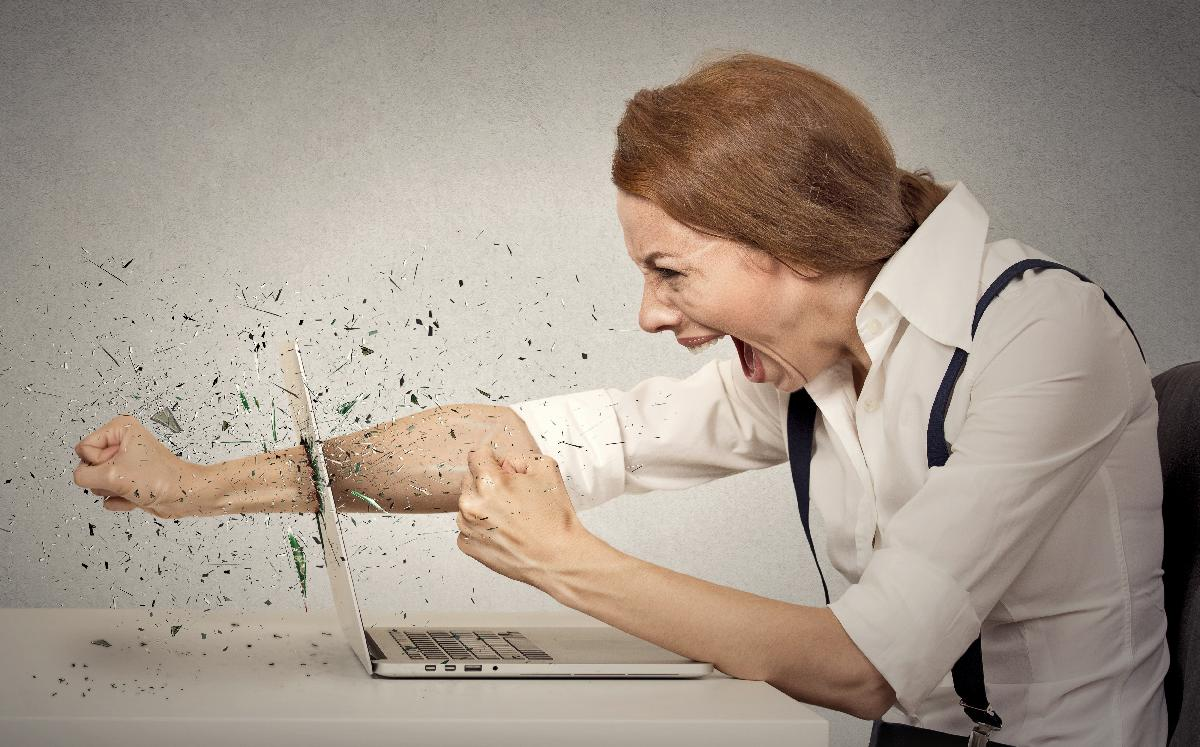

When to put input data by hand?

- If it takes less than a minute

- if your data isn't in electronic form 

## GUI

The variable area of the HOME tab allows you to

- create, edit, and save variables in your workspace

- import all or a portion of .txt, .xls, .csv, .mat, .dat files

- see and name columns of data in file

`uiimport` - command brings up the import GUI

## Command Line Commands

`load` – loads numeric variables into MATLAB

`csvread` – loads numeric values from a .csv file 

`xlsread` – loads texts and numeric values from .xls, .xlsx, .xlsm, .xltx, and .xltm files 

`readtable` – creates a table of variables from the columns of a file

`textscan`  - reads formatted text into a cell array 

`importdata` – loads data (including images) from a file, can specify delimiter and column headings 

## `LOAD`

- works for many file types, (but usually only ascii files,** really I would only use this for .mat files**)

- otherwise data should be numeric – is imported as doubles

load(matfile)

## `IMPORTDATA`

- most general of the functions (can import images)

- can specify delimiter (`delimiterIn`) and header lines (`headerlinesIn`)

- can output MATLAB's best guess at column delimiter (`delimiterOut`) and number of header lines (`headerlinesOut`)

Example setting `' '` (space) as a delimiter (what separates values). importdata reads .csv files well enough.

txtimport = importdata(txtfile," ") 

txtimport = 1.0e+03 *

    1.8500   -0.0003   -0.0003   -0.0002   -0.0003   -0.0002   -0.0004   -0.0002   -0.0003   -0.0002   -0.0004   -0.0001
    1.8510   -0.0003   -0.0003   -0.0002   -0.0003   -0.0002   -0.0004   -0.0002   -0.0003   -0.0002   -0.0004   -0.0002
    1.8520   -0.0003   -0.0003   -0.0002   -0.0003   -0.0002   -0.0003   -0.0002   -0.0003   -0.0002   -0.0004   -0.0002
    1.8530   -0.0003   -0.0003   -0.0002   -0.0003   -0.0002   -0.0003   -0.0002   -0.0003   -0.0002   -0.0004   -0.0002
    1.8540   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0002   -0.0004   -0.0002   -0.0004   -0.0002
    1.8550   -0.0003   -0.0004   -0.0003   -0.0004   -0.0003   -0.0004   -0.0003   -0.0004   -0.0003   -0.0004   -0.0002
    1.8560   -0.0003   -0.0004   -0.0003   -0.0004   -0.0003   -0.0004   -0.0003   -0.0004   -0.0003   -0.0004   -0.0003
    1.8570   -0.0004   -0.0004   -0.0003   -0.0004   -0.0003   -0.0004   -0.0003   -0.0004   -0.0003   -0.0005   -0.0003
    1.858

csvimport = importdata(csvfile)

csvimport = 1.0e+03 *

    1.7005    0.0083   -0.0010   -0.0010    0.0010
    1.7015    0.0183   -0.0010   -0.0010    0.0010
    1.7025    0.0267   -0.0010   -0.0010    0.0010
    1.7035    0.0383   -0.0010   -0.0010    0.0010
    1.7045    0.0600   -0.0010   -0.0010    0.0010
    1.7055    0.0967   -0.0010   -0.0010    0.0010
    1.7065    0.0483   -0.0010   -0.0010    0.0010
    1.7075    0.0333   -0.0010   -0.0010    0.0010
    1.7085    0.0167   -0.0010   -0.0010    0.0010
    1.7095    0.0133   -0.0010   -0.0010    0.0010


## `CSVREAD`

- works for .csv files containing strictly numeric values

- stores all values in large matrix M

- can start at arbitrary column and row, *R1 C1 …*

Example using .csv file 

csv = csvread(csvfile)

csv = 1.0e+03 *

    1.7005    0.0083   -0.0010   -0.0010    0.0010
    1.7015    0.0183   -0.0010   -0.0010    0.0010
    1.7025    0.0267   -0.0010   -0.0010    0.0010
    1.7035    0.0383   -0.0010   -0.0010    0.0010
    1.7045    0.0600   -0.0010   -0.0010    0.0010
    1.7055    0.0967   -0.0010   -0.0010    0.0010
    1.7065    0.0483   -0.0010   -0.0010    0.0010
    1.7075    0.0333   -0.0010   -0.0010    0.0010
    1.7085    0.0167   -0.0010   -0.0010    0.0010
    1.7095    0.0133   -0.0010   -0.0010    0.0010


## `XLSREAD`

- reads all numeric data into the matrix X 

- can specify excel sheet and range

- can include output variables to capture text

Example using a quite complicated .xlsx file

Xlsx = xlsread(xlsfile, 'Global Carbon Budget','A23:F78')

Xlsx = 1.0e+03 *

    1.9600    0.0025    0.0017    0.0015    0.0008    0.0013
    1.9610    0.0026    0.0016    0.0017    0.0007    0.0007
    1.9620    0.0026    0.0016    0.0012    0.0008    0.0014
    1.9630    0.0028    0.0015    0.0012    0.0009    0.0010
    1.9640    0.0029    0.0015    0.0010    0.0011    0.0015
    1.9650    0.0031    0.0014    0.0023    0.0012    0.0005
    1.9660    0.0032    0.0014    0.0023    0.0012    0.0014
    1.9670    0.0033    0.0014    0.0013    0.0010    0.0016
    1.9680    0.0035    0.0014    0.0021    0.0011    0.0024
    1.9690    0.0037    0.0014    0.0028    0.0011    0.0007


[num,text,raw] = xlsread(xlsfile, 'Global Carbon Budget','A20:F79')

num = 1.0e+03 *

    1.9590    0.0024    0.0018    0.0020    0.0009    0.0007
    1.9600    0.0025    0.0017    0.0015    0.0008    0.0013
    1.9610    0.0026    0.0016    0.0017    0.0007    0.0007
    1.9620    0.0026    0.0016    0.0012    0.0008    0.0014
    1.9630    0.0028    0.0015    0.0012    0.0009    0.0010
    1.9640    0.0029    0.0015    0.0010    0.0011    0.0015
    1.9650    0.0031    0.0014    0.0023    0.0012    0.0005
    1.9660    0.0032    0.0014    0.0023    0.0012    0.0014
    1.9670    0.0033    0.0014    0.0013    0.0010    0.0016
    1.9680    0.0035    0.0014    0.0021    0.0011    0.0024


text = 1×6 cell array
    {'Year'}    {'fossil emissions excluding carbonation'}    {'land-use change emissions'}    {'atmospheric growth'}    {'ocean sink'}    {'land sink'}


raw = 60×6 cell array
    {[ NaN]}    {[                                   NaN]}    {[                      NaN]}    {[               NaN]}    {[       NaN]}    {[      NaN]}
    {'Year'}    {'fossil emissions excluding carbonation'}    {'land-use change emissions'}    {'atmospheric growth'}    {'ocean sink'}    {'land sink'}
    {[1959]}    {[                                2.4150]}    {[                   1.8042]}    {[            2.0448]}    {[    0.8614]}    {[   0.6774]}
    {[1960]}    {[                                2.5480]}    {[                   1.6594]}    {[            1.5123]}    {[    0.8391]}    {[   1.2584]}
    {[1961]}    {[                                2.5530]}    {[                   1.5936]}    {[            1.6614]}    {[    0.7165]}    {[   0.6603]}
    {[1962]}    {[                                2.6440]}    {[                   1.5559]}    {[            1.1928]}    {[    0.7684]}    {[   1.4082]}
    {[1963]}    {[                                2.7940]}  

The advanced option for reading data from an xlsx file may be to capture the headers as well. You can do this with the following

rawT = cell2table(raw(2:end,:))

rawT = 59×6 table
      Var1                         Var2                                   Var3                          Var4                  Var5             Var6     
    ________    __________________________________________    _____________________________    ______________________    ______________    _____________

    {'Year'}    {'fossil emissions excluding carbonation'}    {'land-use change emissions'}    {'atmospheric growth'}    {'ocean sink'}    {'land sink'}
    {[1959]}    {[                                2.4150]}    {[                   1.8042]}    {[            2.0448]}    {[    0.8614]}    {[   0.6774]}
    {[1960]}    {[                                2.5480]}    {[                   1.6594]}    {[            1.5123]}    {[    0.8391]}    {[   1.2584]}
    {[1961]}

match = [" " , "-"];
newraw = erase(raw(1,:),match);

Error using erase
First argument must be text.

% spaces are no good in table header names
rawT.Properties.VariableNames = newraw

## `READTABLE`

- creates a table from column data in a file

- `T` contains one variable per column in data file

Ttxt = readtable(txtfile)

Ttxt = 168×12 table
    Var1     Var2      Var3      Var4      Var5      Var6      Var7      Var8      Var9     Var10     Var11     Var12 
    ____    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    1850    -0.274    -0.327    -0.241    -0.323    -0.224    -0.395    -0.152    -0.348    -0.211    -0.418    -0.138
    1851    -0.271    -0.324    -0.239     -0.32    -0.222    -0.356    -0.186    -0.345    -0.209    -0.385    -0.166
    1852    -0.271    -0.324    -0.239    -0.319    -0.224    -0.331    -0.211    -0.344    -0.

Tcsv = readtable(csvfile)

Tcsv = 316×5 table
     Var1     Var2    Var3    Var4    Var5
    ______    ____    ____    ____    ____

    1700.5     8.3     -1      -1      1  
    1701.5    18.3     -1      -1      1  
    1702.5    26.7     -1      -1      1  
    1703.5    38.3     -1      -1      1  
    1704.5      60     -1      -1      1  
    1705.5    96.7     -1      -1      1  
    1706.5    48.3     -1      -1      1  
    1707.5    33.3     -1      -1      1  
    1708.5    16.7     -1      -1      1  
    1709.5    13.3     -1      -1      1  
    1710.5       5     -1      -1      1  
    1711.5       0     -1      -1      1  
    1712.5       0     -1      -1      1  
    1713.5     3.3     -1      -1      1  
    1714.5    18.3     -1      -1      1  
    1715.5      45     -1      -1      1  


Txls = readtable(xlsfile) % No so good with excel files

Txls = 25×1 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            TheGlobalCarbonBudget2020IsACollaborativeEffortOfTheGlobalCarbo                                                                                                                                                          

## `TEXTSCAN`

- reads formatted data from a file or string (must use `fopen``() `and `fclose``()`)

- stores any type of data in cell array *C*

- must specify the exact format in <`formatSpec`> using *conversion specifiers*

- this function is also good at filtering through character and string arrays based on conversion specifiers

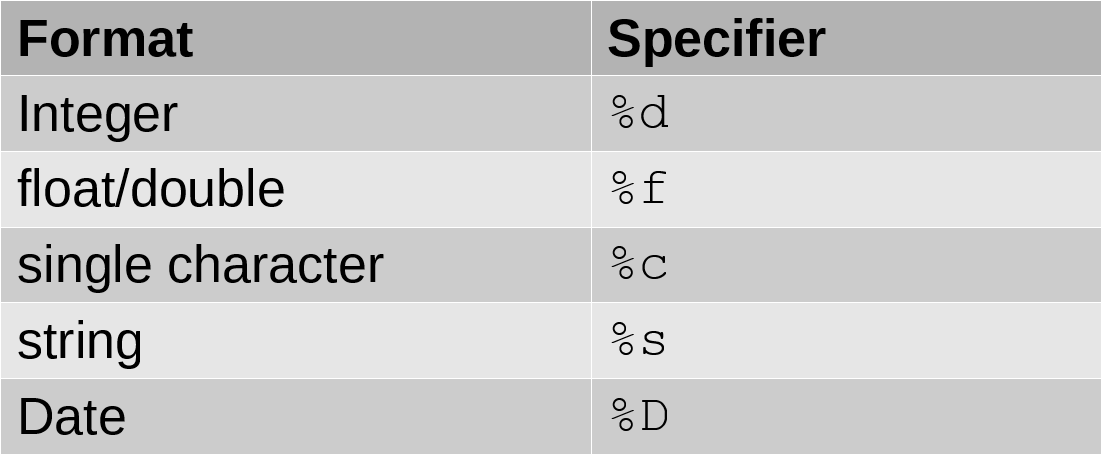

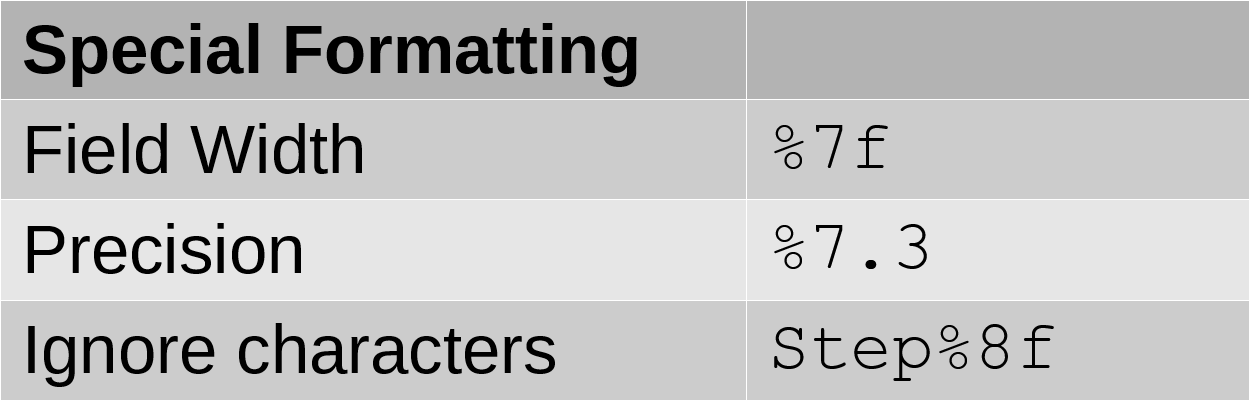

fid = fopen(txtfile)

fid = 3

N = 171;
scantxt = textscan(fid,'%f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f %.4f',N)

scantxt = 1×12 cell array
    {168×1 double}    {168×1 double}    {168×1 double}    {168×1 double}    {168×1 double}    {168×1 double}    {168×1 double}    {168×1 double}    {168×1 double}    {168×1 double}    {168×1 double}    {168×1 double}


fclose(fid);

## Outputting Data

Saving your processed variables is a good idea

Save your workspace (.mat files)

Output the data into a file with commands

- `dlmwrite`

- `csvwrite`

- `xlswrite`

- `writetable`

## `DLMWRITE`

- writes the data array *M* to `<filename> `(any ascii file)

- adds to an existing file with `'-append'`

- specify delimiter or row/column offsets with `Name,Value`pairs or further arguments

## `CSVWRITE`

- writes data array *M *to a *.csv*file

- specify starting row and column of the *.csv*file with <row> and <col>

- *M *must be numeric

- *.csv *file carries only 5 digits of precision   

## `XLSWRITE`

- writes data array *A *to an excel spreadsheet

- *A *can be any type of array

- specify specific sheets and cell ranges to write data to the spreadsheet

## `WRITETABLE`

- writes table *T* to <filename> OR *T.txt*

- each column of each variable in *T *becomes a column in the output file

- variable names of *T* become column headings in the first line of the file